# Read Images from a Datastore

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code creates `ds `and a logical array `idxDead` that is `true` for dead roundworm images.

ds = imageDatastore("./images/antibioticResponse", "IncludeSubfolders", true, "LabelSource", "foldernames")

ds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Batch_Processing\images\antibioticResponse\alive\wormA01.jpg';
                              ' ...\Batch_Processing\images\antibioticResponse\alive\wormA02.jpg';
                              ' ...\Batch_Processing\images\antibioticResponse\alive\wormA03.jpg'
                               ... and 90 more
                              }
                     Folders: {
                              ' ...\Batch_Processing\images\antibioticResponse'
                              }
                      Labels: [alive; alive; alive ... and 90 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


idxDead = ds.Labels == "dead";

## Task 1

The datastore `ds` has already been created and labeled, so you're ready to read and process the roundworm images.

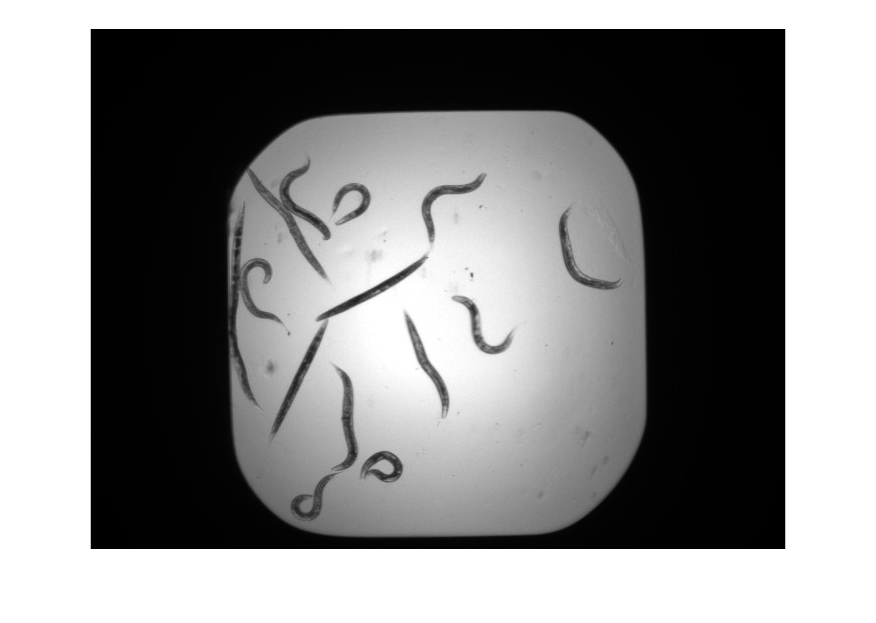

I = read(ds);
imshow(I)

## Task 2

Looks like those worms were alive. A second call to `read` will load the next image in the datastore. Adding a second output to the read function will provide you with information about that file.

`[``I``,``info``]` `=` `read``(``ds``)`

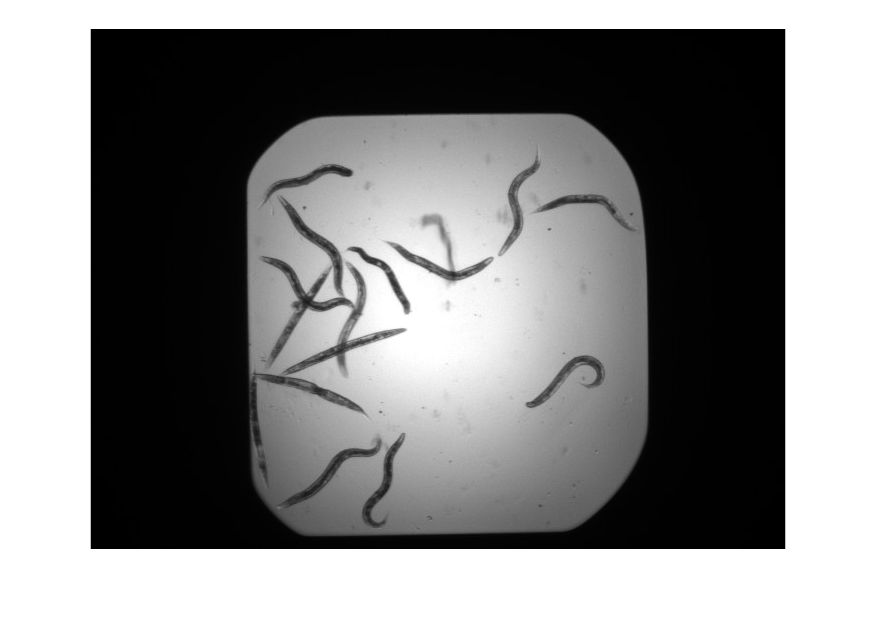

[I2, info] = read(ds);
imshow(I2)

## Task 3

Did the image contain live or dead worms? You can validate your answer by looking at the `Label` field of the structure `info`.

label2 = info.Label

label2 = categorical
     alive 


## Task 4

Which images in the datastore contain dead worms? You can use the `find` function to locate the index of an image of dead worms and then read it with `readimage``(``ds``,``k``)`. The logical array `idxDead` has values of `1` for images that contain dead worms.

`find``(``u``,``k``)` returns the linear indices for the first `k` nonzero entries in `u`. For example

`u` `=` `[``0` `0` `1` `1``]`

`idx` `=` `find``(``u``,``1``)`

returns `idx` `=` `3`, the index of first nonzero element in `u`.

idx = find(idxDead, 1)

idx = 49

## Task 5

Now that you know which image has dead worms, you can read it with `readimage`.

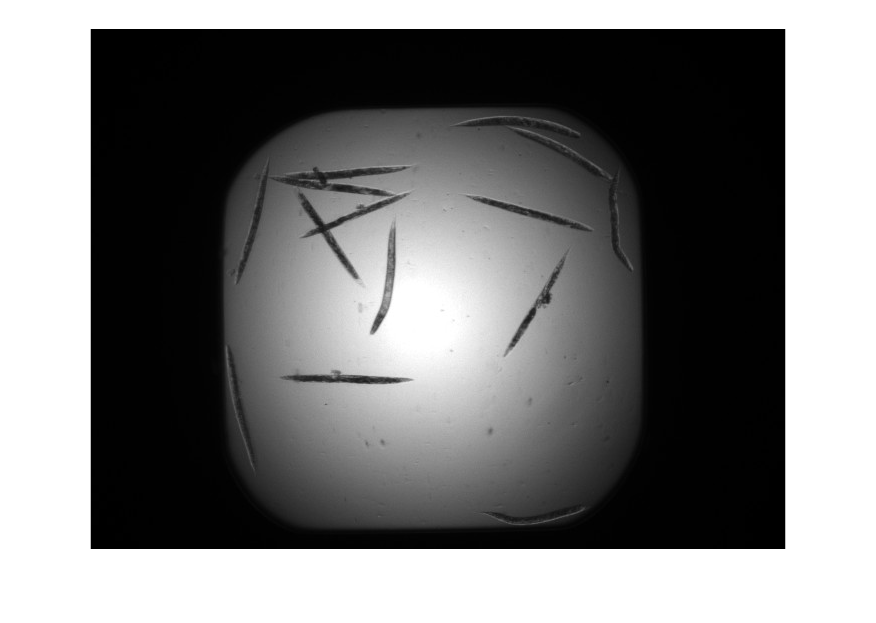

I3 = readimage(ds, idx);
imshow(I3)